# **Question 2**

clc; clear;

load t
load u
load y

N = length(y);

% trying orders of 1 to 6
for n=1:6
    m = n;
    
    U = arx_U_builder(n,m,u,y);

    fprintf("\n\n\n")
    fprintf("\n\n U = \n")
    
    disp(U(1:10,:))

    rnk = rank(U'*U);
    reference = min(size(U));
    if (rnk == reference)
        temp = n;
        fprintf(">>> Full Rank U for order of %d \n", n)
        disp("------------------------------------------")
    else
        fprintf(">>> Rank Deficient of U for order of %d \n", n)
        disp("------------------------------------------")
    end
end



 U = 


         0   -1.5000         0
         0   -1.5000   -1.5000
         0   -1.5000   -1.5000
         0   -1.5000   -1.5000
    1.5000   -1.5000   -1.5000
    0.0698   -1.5000   -1.5000
    1.0171   -1.5000   -1.5000
    0.4931   -1.5000   -1.5000
    0.7363   -1.5000   -1.5000
    0.6579   -1.5000   -1.5000



>>> Full Rank U for order of 1 


------------------------------------------




 U = 


         0         0   -1.5000         0         0
         0         0   -1.5000   -1.5000         0
         0         0   -1.5000   -1.5000   -1.5000
         0         0   -1.5000   -1.5000   -1.5000
    1.5000         0   -1.5000   -1.5000   -1.5000
    0.0698    1.5000   -1.5000   -1.5000   -1.5000
    1.0171    0.0698   -1.5000   -1.5000   -1.5000
    0.4931    1.0171   -1.5000   -1.5000   -1.5000
    0.7363    0.4931   -1.5000   -1.5000   -1.5000
    0.6579    0.7363   -1.5000   -1.5000   -1.5000



>>> Full Rank U for order of 2 


------------------------------------------




 U = 


         0         0         0   -1.5000         0         0         0
         0         0         0   -1.5000   -1.5000         0         0
         0         0         0   -1.5000   -1.5000   -1.5000         0
         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000
    1.5000         0         0   -1.5000   -1.5000   -1.5000   -1.5000
    0.0698    1.5000         0   -1.5000   -1.5000   -1.5000   -1.5000
    1.0171    0.0698    1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.4931    1.0171    0.0698   -1.5000   -1.5000   -1.5000   -1.5000
    0.7363    0.4931    1.0171   -1.5000   -1.5000   -1.5000   -1.5000
    0.6579    0.7363    0.4931   -1.5000   -1.5000   -1.5000   -1.5000



>>> Full Rank U for order of 3 


------------------------------------------




 U = 


         0         0         0         0   -1.5000         0         0         0         0
         0         0         0         0   -1.5000   -1.5000         0         0         0
         0         0         0         0   -1.5000   -1.5000   -1.5000         0         0
         0         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000         0
    1.5000         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.0698    1.5000         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    1.0171    0.0698    1.5000         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.4931    1.0171    0.0698    1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.7363    0.4931    1.0171    0.0698   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.6579    0.7363    0.4931    1.0171   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000



>>> Full Rank U for order of 4 


------------------------------------------




 U = 


         0         0         0         0         0   -1.5000         0         0         0         0         0
         0         0         0         0         0   -1.5000   -1.5000         0         0         0         0
         0         0         0         0         0   -1.5000   -1.5000   -1.5000         0         0         0
         0         0         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000         0         0
    1.5000         0         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000         0
    0.0698    1.5000         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    1.0171    0.0698    1.5000         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.4931    1.0171    0.0698    1.5000         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.7363    0.4931    1.0171    0.0698    1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
 

>>> Rank Deficient of U for order of 5 


------------------------------------------




 U = 


         0         0         0         0         0         0   -1.5000         0         0         0         0         0         0
         0         0         0         0         0         0   -1.5000   -1.5000         0         0         0         0         0
         0         0         0         0         0         0   -1.5000   -1.5000   -1.5000         0         0         0         0
         0         0         0         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000         0         0         0
    1.5000         0         0         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000         0         0
    0.0698    1.5000         0         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000         0
    1.0171    0.0698    1.5000         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.4931    1.0171    0.0698    1.5000         0         0   -1.5000   -1.5000   

>>> Rank Deficient of U for order of 6 


------------------------------------------



fprintf(">>> So Taking n=%d as the proper rank for matrix U\n", temp)

>>> So Taking n=4 as the proper rank for matrix U


n = temp;

m = n;
U = arx_U_builder(n,m,u,y);
disp("U = ")

U = 


disp(U(1:10,:))

         0         0         0         0   -1.5000         0         0         0         0
         0         0         0         0   -1.5000   -1.5000         0         0         0
         0         0         0         0   -1.5000   -1.5000   -1.5000         0         0
         0         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000         0
    1.5000         0         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.0698    1.5000         0         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    1.0171    0.0698    1.5000         0   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.4931    1.0171    0.0698    1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.7363    0.4931    1.0171    0.0698   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000
    0.6579    0.7363    0.4931    1.0171   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000



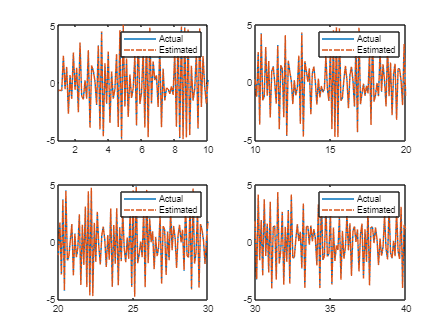


theta_hat = inv(U'*U)*U'*y;
y_hat = U*theta_hat;

figure()

subplot(2,2,1)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([1,10])

subplot(2,2,2)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([10,20])

subplot(2,2,3)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([20,30])

subplot(2,2,4)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([30,40])

%% Evaluation Metrics

disp("----------------Model Evaaluation Report-------------------")

----------------Model Evaaluation Report-------------------



SST = sum((y-mean(y)).^2);
SSE = sum((y-y_hat).^2);

R2 = 1 - (SSE/SST);

MSE = SSE/N;

fprintf('------> SSE : %.7f \n', SSE);

------> SSE : 0.0000000 


fprintf('------> MSE : %.7f \n', MSE);

------> MSE : 0.0000000 


fprintf('------> R2  : %.7f \n', R2);

------> R2  : 1.0000000 



disp("===========================================================")

The greater the R parameter, the better the model. Accordingly, this method seems to be a better option rather than the previous method.